%---------------------------------------------------------- 
%------------------ONLY INPUT HERE-------------------------
%----------------------------------------------------------
    % --- Inputs:
    % m_flowrate [kg/s]
    % option array
    % Kinetic_type = "LHHW" or "Simple Power";
    % Pressure_drop = "Yes" or "No";
    % Temp_dependence = "Yes" or "No";

m_flowrate = 1;
reactor_length = 10;
P0 = 1.0; %Initial Pressure [bar]
T0 = 523; %Initial Temperature [K]
Kinetic_type = "LHHW";
Pressure_drop = "Yes";
Temp_dependence = "No";
%----------------------------------------------------------
%----------------------------------------------------------
%----------------------------------------------------------

option = [Kinetic_type Pressure_drop Temp_dependence];

Nt_range = 1500:200:2500;% range of number of tubes
L_range = 1:1:15;% range of length



Productivity = zeros(length(Nt_range), length(L_range));% we set the productivity to a matrix of all zeroes waiting to be filled

for i = 1:length(Nt_range) %i is the columns of the matrix of productivity 

    Nt = Nt_range(i);
    m_tube = m_flowrate/Nt;

    for j = 1:length(L_range)%j is the rows of the matrix of productivity 

        L = L_range(j);
        [z_points, F_CH3OH, F_O2, F_HCHO, F_H2O, F_CO, F_N2, extent1, extent2, P, T]=solve_reactor(m_tube,L, P0, T0, option);
        
        F_out = F_HCHO(end);
        Productivity(i,j) = Nt.*F_out;
    end
end

z_points =          0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH =     0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028    0.0027    0.0026    0.0025    0.0025    0.0024    0.0023    0.0023    0.0022    0.0022


F_O2 =     0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013


F_HCHO =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016


F_H2O =     0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0023


F_CO = 1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691    0.0774    0.0899    0.1025    0.1151    0.1253    0.1353    0.1450    0.1525    0.1551


F_N2 =     0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230    0.1297    0.1391    0.1480    0.1564    0.1629    0.1692    0.1752    0.1797    0.1813


extent2 = 1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768    0.0860    0.0999    0.1139    0.1279    0.1392    0.1503    0.1611    0.1694    0.1723


P =     1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748    0.7551    0.7251    0.6938    0.6609    0.6328    0.6034    0.5725    0.5467    0.5372


T =    523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points =          0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH =     0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028    0.0027    0.0026    0.0025    0.0025    0.0024    0.0023    0.0023    0.0022    0.0022    0.0022    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020


F_O2 =     0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012


F_HCHO =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0017    0.0017    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018


F_H2O =     0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0024    0.0025    0.0025    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0026


F_CO = 1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691    0.0774    0.0899    0.1025    0.1151    0.1253    0.1353    0.1450    0.1522    0.1592    0.1660    0.1708    0.1754    0.1798    0.1829    0.1859    0.1887    0.1907    0.1926    0.1944    0.1956


F_N2 =     0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230    0.1297    0.1391    0.1480    0.1564    0.1629    0.1692    0.1752    0.1795    0.1838    0.1879    0.1908    0.1937    0.1964    0.1984    0.2004    0.2023    0.2037    0.2050    0.2064    0.2073


extent2 = 1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768    0.0860    0.0999    0.1139    0.1279    0.1392    0.1503    0.1611    0.1692    0.1769    0.1844    0.1898    0.1949    0.1998    0.2032    0.2065    0.2097    0.2119    0.2140    0.2159    0.2173


P =     1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748    0.7551    0.7251    0.6938    0.6609    0.6328    0.6034    0.5725    0.5476    0.5215    0.4940    0.4724    0.4498    0.4259    0.4073    0.3878    0.3672    0.3511    0.3343    0.3166    0.3027


T =    523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points =          0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH =     0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028    0.0027    0.0026    0.0025    0.0025    0.0024    0.0023    0.0023    0.0022    0.0022    0.0022    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020


F_O2 =     0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012


F_HCHO =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0017    0.0017    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018


F_H2O =     0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0024    0.0025    0.0025    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0026


F_CO = 1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691    0.0774    0.0899    0.1025    0.1151    0.1253    0.1353    0.1450    0.1522    0.1592    0.1660    0.1708    0.1754    0.1798    0.1829    0.1859    0.1887    0.1907    0.1926    0.1944    0.1956


F_N2 =     0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230    0.1297    0.1391    0.1480    0.1564    0.1629    0.1692    0.1752    0.1795    0.1838    0.1879    0.1908    0.1937    0.1964    0.1984    0.2004    0.2023    0.2037    0.2050    0.2064    0.2073


extent2 = 1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768    0.0860    0.0999    0.1139    0.1279    0.1392    0.1503    0.1611    0.1692    0.1769    0.1844    0.1898    0.1949    0.1998    0.2032    0.2065    0.2097    0.2119    0.2140    0.2159    0.2173


P =     1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748    0.7551    0.7251    0.6938    0.6609    0.6328    0.6034    0.5725    0.5476    0.5215    0.4940    0.4724    0.4498    0.4259    0.4073    0.3878    0.3672    0.3511    0.3343    0.3166    0.3027


T =    523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points =          0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH =     0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028    0.0027    0.0026    0.0025    0.0025    0.0024    0.0023    0.0023    0.0022    0.0022    0.0022    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020


F_O2 =     0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012


F_HCHO =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0017    0.0017    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018


F_H2O =     0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0024    0.0025    0.0025    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0026


F_CO = 1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691    0.0774    0.0899    0.1025    0.1151    0.1253    0.1353    0.1450    0.1522    0.1592    0.1660    0.1708    0.1754    0.1798    0.1829    0.1859    0.1887    0.1907    0.1926    0.1944    0.1956


F_N2 =     0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230    0.1297    0.1391    0.1480    0.1564    0.1629    0.1692    0.1752    0.1795    0.1838    0.1879    0.1908    0.1937    0.1964    0.1984    0.2004    0.2023    0.2037    0.2050    0.2064    0.2073


extent2 = 1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768    0.0860    0.0999    0.1139    0.1279    0.1392    0.1503    0.1611    0.1692    0.1769    0.1844    0.1898    0.1949    0.1998    0.2032    0.2065    0.2097    0.2119    0.2140    0.2159    0.2173


P =     1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748    0.7551    0.7251    0.6938    0.6609    0.6328    0.6034    0.5725    0.5476    0.5215    0.4940    0.4724    0.4498    0.4259    0.4073    0.3878    0.3672    0.3511    0.3343    0.3166    0.3027


T =    523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points =          0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH =     0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028    0.0027    0.0026    0.0025    0.0025    0.0024    0.0023    0.0023    0.0022    0.0022    0.0022    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020


F_O2 =     0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012


F_HCHO =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0017    0.0017    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018


F_H2O =     0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0024    0.0025    0.0025    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0026


F_CO = 1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691    0.0774    0.0899    0.1025    0.1151    0.1253    0.1353    0.1450    0.1522    0.1592    0.1660    0.1708    0.1754    0.1798    0.1829    0.1859    0.1887    0.1907    0.1926    0.1944    0.1956


F_N2 = 1×230
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×230
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×230
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×230
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×230
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 230×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×230
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×230
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×230
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×230
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×230
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×230
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×230
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×230
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×230
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×230
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 231×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×231
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×231
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×231
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×231
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×231
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×231
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×231
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×231
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×231
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×231
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 231×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×231
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×231
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×231
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×231
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×231
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×231
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×231
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×231
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×231
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×231
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 231×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×231
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×231
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×231
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×231
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×231
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×231
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×231
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×231
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×231
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×231
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 232×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×232
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×232
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×232
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×232
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×232
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×232
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×232
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×232
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×232
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×232
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 232×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×232
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×232
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×232
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×232
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×232
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×232
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×232
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×232
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×232
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×232
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 232×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×232
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×232
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×232
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×232
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×232
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×232
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×232
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×232
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×232
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×232
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 232×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×232
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×232
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×232
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×232
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×232
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×232
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×232
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×232
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×232
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×232
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 232×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×232
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×232
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×232
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×232
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×232
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×232
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×232
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×232
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×232
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×232
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 232×1
         0
    0.0006
    0.0012
    0.0018
    0.0045
    0.0073
    0.0100
    0.0127
    0.0238
    0.0323


F_CH3OH = 1×232
    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0036    0.0036    0.0035    0.0035    0.0034    0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0030    0.0030    0.0029    0.0028    0.0028


F_O2 = 1×232
    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015


F_HCHO = 1×232
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011


F_H2O = 1×232
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0018


F_CO = 1×232
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0011    0.0018    0.0027    0.0037    0.0049    0.0063    0.0087    0.0114    0.0144    0.0177    0.0213    0.0251    0.0315    0.0383    0.0455    0.0531    0.0610    0.0691


F_N2 = 1×232
    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284    0.0284


extent1 = 1×232
1.0e-05 *

         0    0.0002    0.0004    0.0005    0.0013    0.0021    0.0029    0.0037    0.0069    0.0093    0.0117    0.0141    0.0164    0.0212    0.0259    0.0305    0.0350    0.0394    0.0460    0.0525    0.0587    0.0648    0.0707    0.0764    0.0850    0.0932    0.1011    0.1087    0.1160    0.1230


extent2 = 1×232
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0020    0.0030    0.0041    0.0055    0.0070    0.0097    0.0127    0.0160    0.0197    0.0237    0.0279    0.0350    0.0426    0.0506    0.0590    0.0678    0.0768


P = 1×232
    1.0000    0.9998    0.9996    0.9994    0.9984    0.9974    0.9965    0.9955    0.9916    0.9886    0.9856    0.9825    0.9794    0.9731    0.9667    0.9602    0.9537    0.9472    0.9369    0.9265    0.9160    0.9054    0.8946    0.8837    0.8666    0.8491    0.8311    0.8128    0.7941    0.7748


T = 1×232
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 42×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×42
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×42
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×42
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×42
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×42
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×42
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×42
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×42
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×42
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×42
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 56×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×56
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×56
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×56
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×56
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×56
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×56
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×56
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×56
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×56
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×56
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 80×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×80
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×80
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×80
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×80
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×80
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×80
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×80
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×80
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×80
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×80
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 181×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×181
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×181
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×181
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×181
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×181
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×181
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×181
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×181
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×181
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×181
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 183×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×183
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×183
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×183
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×183
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×183
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×183
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×183
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×183
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×183
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×183
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 184×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×184
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×184
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×184
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×184
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×184
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×184
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×184
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×184
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×184
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×184
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 185×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×185
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×185
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×185
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×185
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×185
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×185
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×185
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×185
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×185
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×185
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 186×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×186
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×186
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×186
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×186
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×186
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×186
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×186
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×186
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×186
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×186
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 186×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×186
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×186
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×186
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×186
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×186
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×186
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×186
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×186
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×186
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×186
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 187×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×187
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×187
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×187
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×187
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×187
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×187
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×187
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×187
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×187
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×187
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 187×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×187
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×187
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×187
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×187
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×187
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×187
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×187
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×187
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×187
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×187
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 187×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×187
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×187
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×187
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×187
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×187
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×187
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×187
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×187
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×187
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×187
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 187×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×187
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×187
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×187
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×187
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×187
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×187
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×187
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×187
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×187
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×187
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 188×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×188
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×188
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×188
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×188
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×188
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×188
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×188
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×188
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×188
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×188
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 188×1
         0
    0.0005
    0.0010
    0.0015
    0.0038
    0.0061
    0.0083
    0.0106
    0.0203
    0.0270


F_CH3OH = 1×188
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0022    0.0022    0.0021    0.0021    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018


F_O2 = 1×188
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


F_HCHO = 1×188
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008


F_H2O = 1×188
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013


F_CO = 1×188
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0044    0.0056    0.0077    0.0102    0.0129    0.0158    0.0191    0.0226    0.0284    0.0348    0.0416    0.0489    0.0566    0.0648


F_N2 = 1×188
    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190    0.0190


extent1 = 1×188
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0011    0.0018    0.0024    0.0031    0.0059    0.0077    0.0096    0.0114    0.0132    0.0167    0.0201    0.0234    0.0266    0.0298    0.0347    0.0394    0.0440    0.0485    0.0528    0.0570    0.0632    0.0692    0.0749    0.0804    0.0856    0.0907


extent2 = 1×188
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0012    0.0019    0.0027    0.0038    0.0049    0.0062    0.0086    0.0113    0.0143    0.0176    0.0212    0.0251    0.0316    0.0386    0.0462    0.0544    0.0629    0.0720


P = 1×188
    1.0000    0.9999    0.9998    0.9998    0.9994    0.9991    0.9987    0.9983    0.9968    0.9958    0.9947    0.9937    0.9926    0.9906    0.9885    0.9865    0.9844    0.9824    0.9791    0.9758    0.9725    0.9692    0.9658    0.9625    0.9573    0.9520    0.9468    0.9415    0.9361    0.9307


T = 1×188
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 48×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×48
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×48
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×48
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×48
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×48
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0015    0.0022    0.0031    0.0041    0.0052    0.0071    0.0092    0.0116    0.0143    0.0172    0.0202    0.0254    0.0311    0.0371    0.0436    0.0505    0.0577


F_N2 = 1×48
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×48
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×48
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0045    0.0057    0.0079    0.0103    0.0129    0.0159    0.0191    0.0225    0.0282    0.0345    0.0413    0.0484    0.0561    0.0641


P = 1×48
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×48
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 62×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×62
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×62
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×62
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×62
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×62
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0015    0.0022    0.0031    0.0041    0.0052    0.0071    0.0092    0.0116    0.0143    0.0172    0.0202    0.0254    0.0311    0.0371    0.0436    0.0505    0.0577


F_N2 = 1×62
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×62
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×62
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0010    0.0017    0.0025    0.0034    0.0045    0.0057    0.0079    0.0103    0.0129    0.0159    0.0191    0.0225    0.0282    0.0345    0.0413    0.0484    0.0561    0.0641


P = 1×62
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×62
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 71×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×71
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×71
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×71
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×71
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×71
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×71
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×71
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×71
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×71
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×71
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 78×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×78
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×78
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×78
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×78
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×78
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×78
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×78
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×78
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×78
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×78
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 90×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×90
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×90
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×90
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×90
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×90
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×90
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×90
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×90
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×90
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×90
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 213×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×213
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×213
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×213
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×213
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×213
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×213
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×213
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×213
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×213
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×213
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 214×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×214
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×214
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×214
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×214
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×214
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×214
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×214
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×214
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×214
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×214
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 215×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×215
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×215
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×215
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×215
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×215
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×215
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×215
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×215
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×215
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×215
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 216×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×216
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×216
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×216
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×216
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×216
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×216
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×216
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×216
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×216
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×216
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 216×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×216
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×216
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×216
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×216
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×216
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×216
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×216
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×216
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×216
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×216
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 217×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×217
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×217
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×217
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×217
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×217
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×217
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×217
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×217
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×217
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×217
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 217×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×217
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×217
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×217
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×217
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×217
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×217
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×217
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×217
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×217
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×217
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 218×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×218
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×218
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×218
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×218
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×218
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×218
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×218
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×218
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×218
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×218
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 218×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×218
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×218
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×218
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×218
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×218
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×218
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×218
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×218
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×218
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×218
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 219×1
         0
    0.0004
    0.0009
    0.0013
    0.0033
    0.0053
    0.0073
    0.0092
    0.0164
    0.0219


F_CH3OH = 1×219
    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0018    0.0017    0.0017    0.0017    0.0016    0.0016    0.0016    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0013    0.0013


F_O2 = 1×219
    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007


F_HCHO = 1×219
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_H2O = 1×219
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010


F_CO = 1×219
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0037    0.0044    0.0050    0.0058


F_N2 = 1×219
    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142


extent1 = 1×219
1.0e-05 *

         0    0.0001    0.0003    0.0004    0.0010    0.0015    0.0021    0.0027    0.0047    0.0063    0.0078    0.0093    0.0108    0.0137    0.0165    0.0192    0.0219    0.0246    0.0284    0.0322    0.0358    0.0393    0.0427    0.0460    0.0509    0.0556    0.0600    0.0643    0.0684    0.0723


extent2 = 1×219
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0019    0.0022    0.0028    0.0035    0.0041    0.0048    0.0056    0.0064


P = 1×219
    1.0000    1.0000    0.9999    0.9999    0.9997    0.9995    0.9994    0.9992    0.9986    0.9981    0.9976    0.9971    0.9966    0.9957    0.9947    0.9937    0.9928    0.9918    0.9903    0.9888    0.9874    0.9859    0.9844    0.9829    0.9806    0.9783    0.9759    0.9736    0.9713    0.9689


T = 1×219
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 50×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×50
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×50
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×50
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×50
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×50
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0014    0.0021    0.0029    0.0038    0.0048    0.0065    0.0085    0.0107    0.0131    0.0157    0.0184    0.0231    0.0282    0.0337    0.0396    0.0458    0.0523


F_N2 = 1×50
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×50
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×50
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0010    0.0016    0.0023    0.0032    0.0042    0.0053    0.0073    0.0094    0.0119    0.0145    0.0174    0.0205    0.0257    0.0314    0.0375    0.0440    0.0509    0.0582


P = 1×50
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×50
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 65×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×65
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×65
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×65
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×65
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×65
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0014    0.0021    0.0029    0.0038    0.0048    0.0065    0.0085    0.0107    0.0131    0.0157    0.0184    0.0231    0.0282    0.0337    0.0396    0.0458    0.0523


F_N2 = 1×65
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×65
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×65
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0010    0.0016    0.0023    0.0032    0.0042    0.0053    0.0073    0.0094    0.0119    0.0145    0.0174    0.0205    0.0257    0.0314    0.0375    0.0440    0.0509    0.0582


P = 1×65
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×65
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 74×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×74
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×74
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×74
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×74
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×74
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×74
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×74
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×74
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×74
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×74
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 80×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×80
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×80
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×80
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×80
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×80
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×80
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×80
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×80
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×80
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×80
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 86×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×86
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×86
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×86
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×86
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×86
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×86
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×86
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×86
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×86
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×86
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 113×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×113
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×113
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×113
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×113
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×113
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×113
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×113
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×113
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×113
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×113
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 122×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×122
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×122
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×122
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×122
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×122
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×122
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×122
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×122
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×122
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×122
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 124×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×124
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×124
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×124
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×124
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×124
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×124
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×124
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×124
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×124
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×124
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 125×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×125
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×125
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×125
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×125
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×125
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×125
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×125
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×125
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×125
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×125
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 126×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×126
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×126
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×126
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×126
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×126
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×126
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×126
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×126
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×126
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×126
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 127×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×127
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×127
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×127
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×127
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×127
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×127
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×127
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×127
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×127
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×127
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 127×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×127
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×127
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×127
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×127
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×127
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×127
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×127
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×127
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×127
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×127
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 128×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×128
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×128
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×128
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×128
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×128
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×128
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×128
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×128
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×128
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×128
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 131×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×131
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×131
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×131
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×131
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×131
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×131
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×131
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×131
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×131
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×131
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 132×1
         0
    0.0004
    0.0008
    0.0012
    0.0030
    0.0047
    0.0065
    0.0083
    0.0141
    0.0189


F_CH3OH = 1×132
    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0010    0.0010


F_O2 = 1×132
1.0e-03 *

    0.8422    0.8417    0.8412    0.8407    0.8383    0.8360    0.8337    0.8314    0.8239    0.8179    0.8121    0.8062    0.8005    0.7893    0.7784    0.7677    0.7573    0.7472    0.7326    0.7184    0.7047    0.6915    0.6787    0.6662    0.6477    0.6300    0.6131    0.5970    0.5814    0.5666


F_HCHO = 1×132
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


F_H2O = 1×132
1.0e+00 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008


F_CO = 1×132
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0018    0.0023    0.0028    0.0034    0.0040    0.0046    0.0052


F_N2 = 1×132
    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114


extent1 = 1×132
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0009    0.0014    0.0019    0.0024    0.0041    0.0054    0.0067    0.0080    0.0093    0.0117    0.0142    0.0165    0.0188    0.0211    0.0243    0.0274    0.0304    0.0334    0.0362    0.0389    0.0430    0.0468    0.0505    0.0541    0.0574    0.0607


extent2 = 1×132
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0015    0.0017    0.0020    0.0026    0.0031    0.0037    0.0044    0.0051    0.0058


P = 1×132
    1.0000    1.0000    1.0000    0.9999    0.9998    0.9997    0.9996    0.9995    0.9992    0.9989    0.9987    0.9984    0.9981    0.9976    0.9971    0.9965    0.9960    0.9955    0.9947    0.9939    0.9931    0.9923    0.9915    0.9907    0.9894    0.9882    0.9869    0.9856    0.9844    0.9831


T = 1×132
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 53×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×53
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×53
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×53
1.0e-03 *

         0    0.0009    0.0019    0.0028    0.0071    0.0114    0.0156    0.0199    0.0326    0.0450    0.0550    0.0648    0.0745    0.0841    0.1031    0.1216    0.1396    0.1571    0.1741    0.1993    0.2235    0.2468    0.2692    0.2909    0.3118    0.3427    0.3720    0.3999    0.4265    0.4517


F_H2O = 1×53
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×53
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0008    0.0011    0.0016    0.0023    0.0031    0.0040    0.0050    0.0067    0.0086    0.0107    0.0130    0.0155    0.0182    0.0226    0.0275    0.0327    0.0382    0.0441


F_N2 = 1×53
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×53
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×53
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0012    0.0018    0.0026    0.0034    0.0044    0.0055    0.0074    0.0095    0.0119    0.0144    0.0172    0.0202    0.0251    0.0305    0.0363    0.0425    0.0490


P = 1×53
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×53
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 68×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×68
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×68
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×68
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×68
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×68
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0008    0.0011    0.0016    0.0023    0.0031    0.0040    0.0050    0.0067    0.0086    0.0107    0.0130    0.0155    0.0182    0.0226    0.0275    0.0327    0.0382    0.0441


F_N2 = 1×68
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×68
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×68
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×68
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×68
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 78×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×78
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×78
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×78
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×78
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×78
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×78
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×78
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×78
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×78
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×78
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 84×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×84
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×84
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×84
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×84
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×84
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×84
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×84
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×84
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×84
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×84
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 118×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×118
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×118
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×118
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×118
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×118
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×118
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×118
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×118
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×118
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×118
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 119×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×119
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×119
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×119
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×119
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×119
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×119
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×119
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×119
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×119
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×119
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 120×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×120
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×120
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×120
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×120
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×120
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×120
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×120
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×120
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×120
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×120
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 121×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×121
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×121
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×121
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×121
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×121
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×121
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×121
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×121
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×121
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×121
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 122×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×122
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×122
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×122
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×122
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×122
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×122
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×122
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×122
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×122
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×122
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 123×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×123
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×123
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×123
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×123
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×123
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×123
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×123
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×123
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×123
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×123
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 123×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×123
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×123
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×123
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×123
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×123
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×123
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×123
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×123
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×123
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×123
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 124×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×124
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×124
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×124
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×124
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×124
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×124
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×124
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×124
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×124
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×124
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 124×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×124
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×124
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×124
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×124
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×124
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×124
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×124
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×124
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×124
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×124
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 125×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×125
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×125
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×125
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×125
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×125
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×125
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×125
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×125
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×125
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×125
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 125×1
         0
    0.0004
    0.0007
    0.0011
    0.0027
    0.0043
    0.0060
    0.0076
    0.0126
    0.0176


F_CH3OH = 1×125
    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0008


F_O2 = 1×125
1.0e-03 *

    0.7019    0.7014    0.7009    0.7004    0.6983    0.6962    0.6940    0.6919    0.6856    0.6793    0.6743    0.6694    0.6645    0.6597    0.6501    0.6408    0.6318    0.6229    0.6143    0.6015    0.5893    0.5774    0.5659    0.5549    0.5441    0.5282    0.5131    0.4986    0.4848    0.4716


F_HCHO = 1×125
1.0e+00 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005


F_H2O = 1×125
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


F_CO = 1×125
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0023    0.0027    0.0033    0.0038    0.0044


F_N2 = 1×125
    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095    0.0095


extent1 = 1×125
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0008    0.0013    0.0017    0.0022    0.0036    0.0050    0.0061    0.0072    0.0083    0.0094    0.0115    0.0135    0.0155    0.0175    0.0194    0.0222    0.0249    0.0275    0.0301    0.0325    0.0348    0.0383    0.0416    0.0448    0.0478    0.0507


extent2 = 1×125
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0010    0.0012    0.0014    0.0017    0.0020    0.0025    0.0031    0.0036    0.0042    0.0049


P = 1×125
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9998    0.9997    0.9995    0.9993    0.9992    0.9990    0.9988    0.9987    0.9984    0.9980    0.9977    0.9974    0.9971    0.9966    0.9961    0.9956    0.9951    0.9946    0.9941    0.9933    0.9926    0.9918    0.9910    0.9902


T = 1×125
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 53×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×53
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×53
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×53
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×53
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×53
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0007    0.0013    0.0022    0.0033    0.0046    0.0061    0.0078    0.0098    0.0119    0.0142    0.0167    0.0194    0.0238    0.0287    0.0338    0.0393    0.0451    0.0511    0.0589


F_N2 = 1×53
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×53
1.0e-06 *

         0    0.0010    0.0020    0.0029    0.0074    0.0118    0.0161    0.0205    0.0329    0.0451    0.0570    0.0688    0.0962    0.1224    0.1477    0.1720    0.1955    0.2197    0.2429    0.2653    0.2870    0.3078    0.3280    0.3585    0.3875    0.4150    0.4412    0.4661    0.4899    0.5178


extent2 = 1×53
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0015    0.0025    0.0037    0.0051    0.0067    0.0087    0.0109    0.0132    0.0158    0.0186    0.0215    0.0265    0.0319    0.0376    0.0437    0.0501    0.0568    0.0655


P = 1×53
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×53
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 67×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×67
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×67
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×67
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×67
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×67
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0007    0.0013    0.0022    0.0033    0.0046    0.0061    0.0078    0.0098    0.0119    0.0142    0.0167    0.0194    0.0238    0.0287    0.0338    0.0393    0.0451    0.0511    0.0589


F_N2 = 1×67
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×67
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×67
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×67
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×67
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 76×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×76
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×76
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×76
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×76
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×76
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×76
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×76
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×76
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×76
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×76
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 110×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×110
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×110
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×110
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×110
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×110
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×110
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×110
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×110
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×110
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×110
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×114
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×114
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×114
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×114
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×114
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×114
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 115×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×115
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×115
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×115
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×115
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×115
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×115
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×115
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×115
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×115
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×115
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 116×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×116
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×116
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×116
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×116
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×116
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×116
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×116
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×116
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×116
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×116
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 117×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×117
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×117
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×117
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×117
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×117
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×117
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×117
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×117
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×117
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×117
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 117×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×117
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×117
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×117
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×117
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×117
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×117
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×117
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×117
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×117
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×117
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 118×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×118
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×118
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×118
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×118
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×118
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×118
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×118
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×118
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×118
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×118
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 118×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×118
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×118
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×118
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×118
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×118
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×118
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×118
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×118
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×118
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×118
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 119×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×119
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×119
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×119
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×119
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×119
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×119
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×119
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×119
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×119
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×119
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 119×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×119
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×119
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×119
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×119
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×119
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×119
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×119
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×119
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×119
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×119
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 119×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×119
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×119
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×119
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×119
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×119
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×119
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×119
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×119
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×119
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×119
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 119×1
         0
    0.0003
    0.0007
    0.0010
    0.0025
    0.0040
    0.0056
    0.0071
    0.0115
    0.0159


F_CH3OH = 1×119
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006


F_O2 = 1×119
1.0e-03 *

    0.6016    0.6011    0.6007    0.6003    0.5983    0.5963    0.5943    0.5924    0.5868    0.5813    0.5759    0.5706    0.5583    0.5464    0.5350    0.5239    0.5133    0.5024    0.4918    0.4816    0.4717    0.4622    0.4530    0.4391    0.4258    0.4132    0.4011    0.3896    0.3786    0.3656


F_HCHO = 1×119
1.0e-03 *

         0    0.0009    0.0018    0.0026    0.0066    0.0106    0.0145    0.0184    0.0296    0.0405    0.0513    0.0618    0.0864    0.1100    0.1326    0.1544    0.1753    0.1969    0.2177    0.2376    0.2568    0.2754    0.2933    0.3203    0.3458    0.3701    0.3931    0.4150    0.4358    0.4601


F_H2O = 1×119
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007


F_CO = 1×119
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0024    0.0029    0.0034    0.0039    0.0045    0.0051    0.0059


F_N2 = 1×119
    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081


extent1 = 1×119
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0012    0.0016    0.0020    0.0033    0.0045    0.0057    0.0069    0.0096    0.0122    0.0148    0.0172    0.0195    0.0220    0.0243    0.0265    0.0287    0.0308    0.0328    0.0359    0.0387    0.0415    0.0441    0.0466    0.0490    0.0518


extent2 = 1×119
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0016    0.0019    0.0022    0.0026    0.0032    0.0038    0.0044    0.0050    0.0057    0.0065


P = 1×119
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9995    0.9994    0.9993    0.9990    0.9987    0.9984    0.9981    0.9978    0.9974    0.9971    0.9968    0.9965    0.9961    0.9958    0.9953    0.9948    0.9943    0.9937    0.9932    0.9927    0.9920


T = 1×119
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 55×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×55
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×55
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×55
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×55
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×55
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0012    0.0020    0.0030    0.0042    0.0055    0.0071    0.0089    0.0108    0.0129    0.0152    0.0176    0.0218    0.0262    0.0310    0.0360    0.0414    0.0469    0.0541


F_N2 = 1×55
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×55
1.0e-06 *

         0    0.0009    0.0018    0.0028    0.0069    0.0110    0.0151    0.0192    0.0303    0.0412    0.0519    0.0625    0.0864    0.1094    0.1316    0.1529    0.1734    0.1951    0.2160    0.2360    0.2554    0.2740    0.2921    0.3194    0.3452    0.3698    0.3931    0.4153    0.4365    0.4614


extent2 = 1×55
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0014    0.0023    0.0033    0.0046    0.0061    0.0079    0.0099    0.0120    0.0144    0.0169    0.0196    0.0242    0.0291    0.0344    0.0401    0.0460    0.0521    0.0602


P = 1×55
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×55
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 69×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×69
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×69
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×69
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×69
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×69
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0012    0.0020    0.0030    0.0042    0.0055    0.0071    0.0089    0.0108    0.0129    0.0152    0.0176    0.0218    0.0262    0.0310    0.0360    0.0414    0.0469    0.0541


F_N2 = 1×69
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×69
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×69
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×69
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×69
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 79×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×79
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×79
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×79
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×79
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×79
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×79
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×79
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×79
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×79
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×79
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 106×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×106
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×106
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×106
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×106
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×106
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×106
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×106
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×106
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×106
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×106
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 109×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×109
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×109
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×109
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×109
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×109
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×109
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×109
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×109
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×109
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×109
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 110×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×110
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×110
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×110
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×110
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×110
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×110
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×110
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×110
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×110
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×110
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 111×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×111
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×111
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×111
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×111
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×111
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×111
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×111
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×111
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×111
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×111
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 112×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×112
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×112
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×112
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×112
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×112
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×112
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×112
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×112
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×112
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×112
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 112×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×112
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×112
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×112
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×112
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×112
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×112
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×112
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×112
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×112
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×112
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 113×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×113
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×113
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×113
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×113
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×113
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×113
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×113
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×113
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×113
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×113
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 113×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×113
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×113
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×113
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×113
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×113
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×113
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×113
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×113
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×113
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×113
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×114
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×114
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×114
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×114
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×114
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×114
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×114
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×114
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×114
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×114
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×114
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×114
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×114
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×114
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×114
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0024
    0.0038
    0.0052
    0.0066
    0.0106
    0.0145


F_CH3OH = 1×114
1.0e-03 *

    0.9650    0.9642    0.9634    0.9626    0.9588    0.9551    0.9514    0.9477    0.9378    0.9279    0.9183    0.9088    0.8873    0.8666    0.8466    0.8275    0.8090    0.7895    0.7707    0.7526    0.7352    0.7184    0.7022    0.6776    0.6543    0.6322    0.6112    0.5912    0.5722    0.5498


F_O2 = 1×114
1.0e-03 *

    0.5264    0.5260    0.5256    0.5252    0.5233    0.5214    0.5196    0.5177    0.5127    0.5078    0.5030    0.4983    0.4874    0.4770    0.4670    0.4574    0.4481    0.4382    0.4288    0.4196    0.4108    0.4023    0.3941    0.3816    0.3697    0.3584    0.3477    0.3374    0.3276    0.3161


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0017    0.0025    0.0062    0.0099    0.0136    0.0173    0.0273    0.0371    0.0467    0.0561    0.0777    0.0983    0.1181    0.1372    0.1555    0.1749    0.1935    0.2114    0.2286    0.2451    0.2611    0.2852    0.3081    0.3297    0.3502    0.3697    0.3882    0.4098


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0022    0.0026    0.0031    0.0036    0.0041    0.0047    0.0054


F_N2 = 1×114
    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


extent1 = 1×114
1.0e-05 *

         0    0.0001    0.0002    0.0003    0.0007    0.0011    0.0015    0.0019    0.0030    0.0041    0.0052    0.0062    0.0086    0.0109    0.0132    0.0153    0.0173    0.0195    0.0216    0.0236    0.0255    0.0274    0.0292    0.0319    0.0345    0.0370    0.0393    0.0415    0.0437    0.0461


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0034    0.0040    0.0046    0.0052    0.0060


P = 1×114
    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9993    0.9991    0.9989    0.9987    0.9985    0.9983    0.9980    0.9978    0.9976    0.9974    0.9971    0.9968    0.9964    0.9961    0.9957    0.9953    0.9950    0.9945


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 56×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×56
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×56
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×56
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×56
1.0e-03 *

    0.1560    0.1567    0.1575    0.1583    0.1618    0.1654    0.1688    0.1723    0.1814    0.1903    0.1991    0.2077    0.2270    0.2456    0.2634    0.2806    0.2972    0.3151    0.3323    0.3489    0.3649    0.3803    0.3952    0.4178    0.4393    0.4597    0.4792    0.4977    0.5154    0.5363


F_CO = 1×56
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0012    0.0019    0.0028    0.0038    0.0050    0.0065    0.0082    0.0100    0.0120    0.0141    0.0163    0.0202    0.0243    0.0287    0.0334    0.0384    0.0436    0.0503


F_N2 = 1×56
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×56
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×56
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0013    0.0021    0.0031    0.0042    0.0056    0.0072    0.0091    0.0111    0.0133    0.0156    0.0181    0.0224    0.0270    0.0319    0.0372    0.0427    0.0484    0.0559


P = 1×56
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×56
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 71×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×71
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×71
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×71
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×71
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×71
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0012    0.0019    0.0028    0.0038    0.0050    0.0065    0.0082    0.0100    0.0120    0.0141    0.0163    0.0202    0.0243    0.0287    0.0334    0.0384    0.0436    0.0503


F_N2 = 1×71
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×71
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×71
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×71
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×71
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 105×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×105
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×105
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×105
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×105
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×105
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×105
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×105
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×105
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×105
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×105
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 107×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×107
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×107
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×107
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×107
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×107
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×107
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×107
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×107
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×107
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×107
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 109×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×109
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×109
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×109
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×109
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×109
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×109
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×109
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×109
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×109
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×109
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 110×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×110
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×110
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×110
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×110
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×110
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×110
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×110
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×110
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×110
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×110
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 111×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×111
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×111
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×111
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×111
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×111
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×111
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×111
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×111
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×111
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×111
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 112×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×112
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×112
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×112
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×112
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×112
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×112
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×112
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×112
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×112
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×112
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 113×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×113
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×113
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×113
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×113
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×113
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×113
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×113
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×113
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×113
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×113
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 113×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×113
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×113
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×113
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×113
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×113
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×113
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×113
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×113
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×113
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×113
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×114
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×114
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×114
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×114
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×114
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×114
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×114
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×114
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×114
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×114
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×114
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×114
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×114
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×114
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×114
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×114
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×114
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×114
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×114
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×114
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×114
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×114
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×114
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 115×1
         0
    0.0003
    0.0006
    0.0009
    0.0022
    0.0036
    0.0049
    0.0063
    0.0099
    0.0135


F_CH3OH = 1×115
1.0e-03 *

    0.8578    0.8570    0.8563    0.8555    0.8520    0.8484    0.8450    0.8415    0.8324    0.8235    0.8147    0.8062    0.7869    0.7684    0.7507    0.7336    0.7171    0.6993    0.6823    0.6659    0.6501    0.6349    0.6203    0.5980    0.5769    0.5569    0.5380    0.5199    0.5028    0.4825


F_O2 = 1×115
1.0e-03 *

    0.4679    0.4675    0.4671    0.4667    0.4650    0.4632    0.4615    0.4597    0.4552    0.4507    0.4463    0.4420    0.4324    0.4231    0.4142    0.4056    0.3973    0.3883    0.3797    0.3714    0.3635    0.3558    0.3483    0.3370    0.3262    0.3160    0.3063    0.2970    0.2882    0.2777


F_HCHO = 1×115
1.0e-03 *

         0    0.0008    0.0016    0.0023    0.0059    0.0094    0.0129    0.0163    0.0254    0.0343    0.0430    0.0516    0.0708    0.0892    0.1069    0.1239    0.1402    0.1578    0.1747    0.1909    0.2065    0.2215    0.2359    0.2578    0.2785    0.2980    0.3165    0.3341    0.3507    0.3703


F_H2O = 1×115
1.0e+00 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


F_CO = 1×115
1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0020    0.0024    0.0029    0.0033    0.0038    0.0044    0.0050


F_N2 = 1×115
    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063


extent1 = 1×115
1.0e-06 *

         0    0.0009    0.0017    0.0026    0.0065    0.0104    0.0143    0.0181    0.0282    0.0381    0.0479    0.0574    0.0788    0.0993    0.1191    0.1381    0.1564    0.1761    0.1950    0.2132    0.2308    0.2477    0.2640    0.2887    0.3121    0.3343    0.3554    0.3754    0.3945    0.4170


extent2 = 1×115
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0016    0.0018    0.0022    0.0027    0.0032    0.0037    0.0043    0.0048    0.0056


P = 1×115
    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9988    0.9986    0.9984    0.9983    0.9981    0.9979    0.9977    0.9974    0.9972    0.9969    0.9966    0.9964    0.9961


T = 1×115
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 57×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×57
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×57
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×57
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×57
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×57
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×57
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×57
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×57
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0012    0.0020    0.0029    0.0040    0.0052    0.0067    0.0085    0.0104    0.0124    0.0146    0.0169    0.0209    0.0253    0.0299    0.0348    0.0400    0.0454    0.0524


P = 1×57
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×57
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 72×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×72
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×72
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×72
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×72
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×72
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×72
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×72
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×72
1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0012    0.0020    0.0029    0.0040    0.0052    0.0067    0.0085    0.0104    0.0124    0.0146    0.0169    0.0209    0.0253    0.0299    0.0348    0.0400    0.0454    0.0524


P = 1×72
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×72
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 107×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×107
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×107
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×107
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×107
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×107
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×107
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×107
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×107
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×107
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×107
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 110×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×110
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×110
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×110
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×110
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×110
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×110
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×110
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×110
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×110
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×110
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 111×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×111
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×111
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×111
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×111
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×111
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×111
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×111
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×111
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×111
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×111
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 112×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×112
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×112
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×112
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×112
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×112
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×112
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×112
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×112
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×112
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×112
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 113×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×113
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×113
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×113
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×113
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×113
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×113
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×113
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×113
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×113
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×113
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×114
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×114
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×114
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×114
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×114
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×114
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×114
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×114
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×114
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×114
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×114
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×114
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×114
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×114
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×114
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×114
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 114×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×114
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×114
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×114
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×114
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×114
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×114
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×114
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×114
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×114
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×114
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 115×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×115
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×115
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×115
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×115
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×115
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×115
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×115
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×115
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×115
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×115
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 115×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×115
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×115
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×115
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×115
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×115
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×115
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×115
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×115
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×115
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×115
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 115×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×115
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×115
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×115
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×115
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×115
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×115
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×115
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×115
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×115
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×115
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 116×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×116
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×116
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×116
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×116
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×116
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×116
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×116
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×116
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×116
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×116
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


z_points = 116×1
         0
    0.0003
    0.0006
    0.0008
    0.0021
    0.0034
    0.0047
    0.0060
    0.0093
    0.0126


F_CH3OH = 1×116
1.0e-03 *

    0.7720    0.7713    0.7706    0.7698    0.7665    0.7631    0.7598    0.7565    0.7482    0.7400    0.7320    0.7241    0.7067    0.6899    0.6739    0.6584    0.6435    0.6272    0.6116    0.5966    0.5821    0.5682    0.5548    0.5344    0.5152    0.4969    0.4796    0.4632    0.4475    0.4290


F_O2 = 1×116
1.0e-03 *

    0.4211    0.4207    0.4204    0.4200    0.4183    0.4167    0.4150    0.4134    0.4092    0.4051    0.4011    0.3971    0.3884    0.3800    0.3719    0.3641    0.3566    0.3484    0.3405    0.3329    0.3256    0.3186    0.3117    0.3014    0.2915    0.2822    0.2733    0.2649    0.2568    0.2472


F_HCHO = 1×116
1.0e-03 *

         0    0.0007    0.0015    0.0022    0.0056    0.0089    0.0122    0.0155    0.0238    0.0320    0.0400    0.0479    0.0653    0.0819    0.0979    0.1133    0.1281    0.1442    0.1597    0.1745    0.1888    0.2025    0.2157    0.2357    0.2546    0.2724    0.2893    0.3053    0.3204    0.3383


F_H2O = 1×116
1.0e-03 *

    0.1404    0.1411    0.1418    0.1426    0.1459    0.1493    0.1526    0.1559    0.1642    0.1724    0.1805    0.1884    0.2059    0.2227    0.2388    0.2544    0.2694    0.2858    0.3016    0.3168    0.3314    0.3455    0.3591    0.3799    0.3995    0.4182    0.4359    0.4528    0.4690    0.4881


F_CO = 1×116
1.0e-04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0011    0.0018    0.0026    0.0036    0.0047    0.0061    0.0076    0.0093    0.0112    0.0131    0.0152    0.0189    0.0227    0.0269    0.0313    0.0360    0.0408    0.0472


F_N2 = 1×116
    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057


extent1 = 1×116
1.0e-06 *

         0    0.0008    0.0016    0.0024    0.0062    0.0099    0.0136    0.0172    0.0265    0.0356    0.0445    0.0533    0.0726    0.0912    0.1091    0.1263    0.1428    0.1609    0.1783    0.1949    0.2110    0.2264    0.2413    0.2640    0.2854    0.3057    0.3249    0.3432    0.3606    0.3811


extent2 = 1×116
1.0e-06 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0015    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0045    0.0052


P = 1×116
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9988    0.9987    0.9986    0.9985    0.9983    0.9981    0.9979    0.9977    0.9975    0.9973    0.9971


T = 1×116
   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523   523


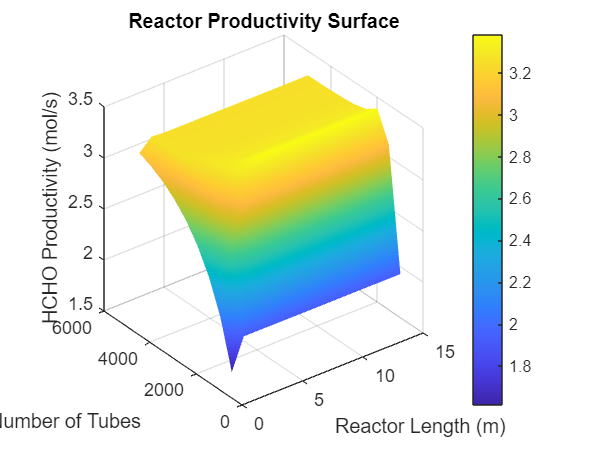


[L_mesh, Nt_mesh] = meshgrid(L_range, Nt_range);

figure
surf(L_mesh, Nt_mesh, Productivity)

xlabel('Reactor Length (m)')
ylabel('Number of Tubes')
zlabel('HCHO Productivity (mol/s)')
title('Reactor Productivity Surface')

shading interp
colorbar

function [r1, r2] = rates_LHHW(T, alpha, P_CH3OH, P_O2, P_H20, P_HCHO)
    
    % --- Inputs:
    %
    % T ~ Temperature [K]
    % alpha ~ Fraction of the mass of catalyst containing the catalytic compounds
    % P_i ~ Partial pressures of each component [atm]
    %
    % --- Outputs:
    %
    % r1 ~ rate of partial oxidation of ethanol [mol/(kg*s)]
    % r2 ~ rate of partial oxidation of carbon monoxide [mol/(kg*s)]

    R = 8.314; % J/mol/K
    
    % --- Activation Energy parameters (converted kJ/mol -> J/mol) --- %
    A_kCH3OH = 1.50e7;   Ea_kCH3OH = 86.00e3;
    A_KCH3OH = 2.60e-4;  Ea_KCH3OH = -56.78e3;
    A_KO2    = 1.42e-5;  Ea_KO2    = -60.32e3;
    A_KH2O   = 5.50e-7;  Ea_KH2O   = -86.45e3;
    A_kCO    = 3.50e2;   Ea_kCO    = 46.00e3;
    
    % --- Calculation of rate constants from params --- %
    kCH3OH = A_kCH3OH * exp(-Ea_kCH3OH/(R*T));
    KCH3OH = A_KCH3OH * exp(-Ea_KCH3OH/(R*T));
    KO2    = A_KO2    * exp(-Ea_KO2/(R*T));
    KH2O   = A_KH2O   * exp(-Ea_KH2O/(R*T));
    kCO    = A_kCO    * exp(-Ea_kCO/(R*T));
    
    P_O2 = sqrt(max(P_O2, 0));
    % --- r1
    nom1 = alpha*kCH3OH*KCH3OH*P_CH3OH*KO2*(P_O2);
    den1 = (1+KCH3OH*P_CH3OH + KH2O*P_H20)*(1 + KO2*(P_O2));
    r1 = nom1 / den1;

    % --- r2
    nom2 = alpha*kCO*P_HCHO*KO2*(P_O2);
    den2 = 1 + KO2*(P_O2);
    r2 = nom2 / den2;
end

function [r1, r2] = rates_powerlaw(T, P_CH3OH, P_O2, P_HCHO)
    
    % --- Inputs:
    %
    % T ~ Temperature [K]
    % 
    % P_i ~ Partial pressures of each component [atm]
    %
    % --- Outputs:
    %
    % r1 ~ rate of partial oxidation of ethanol [mol/(kg*s)]
    % r2 ~ rate of partial oxidation of carbon monoxide [mol/(kg*s)]


    R = 8.314; % [J/(mol*K)]
    
    % --- Activation Energy parameters [J/mol] --- %
    
    Ea1 = 24.8840e3; Ea2 = 4.4067e4;
    
    % --- k0 parameters --- %

    k01 = 1.4614; k02 = 0.5583;
    
    % --- Calculation of k1 & k2 --- %
    k1 = k01 * exp(Ea1/(R*T));
    k2 = k02 * exp(Ea2/(R*T));

    % --- Powers for each species --- %

    % r1, orders
    % wrt CH3OH
    a=0.53;

    % wrt O2 
    b=0.19;

    %r2, orders averaged
    % wrt HCHO 
    c=0.8635; 

    % wrt O2
    d=0.2149;

    %P_CH3OH = P_CH3OH*10^5;
    %P_O2 = P_O2*10^5;
    %P_HCHO = P_HCHO*10^5;

    r1 = k1*(P_CH3OH^a)*(P_O2^b);
    r2 = k2*(P_HCHO^c)*(P_O2^d);

end

function dni_dz = reactor(t,F,options)


if F(9) <= 0.01  % If pressure too low
    fprintf('WARNING: Pressure too low at z=%.2f, P=%.4f\n', t, F(9));
    dni_dz = zeros(10,1);
    return;
end

% Check for negative molar flows
if any(F(1:6) < 0)
    fprintf('WARNING: Negative flows at z=%.2f\n', t);
    dni_dz = zeros(10,1);
    return;
end


%parameters
rho_cat = 1500; %kg m^-3
bed_voidage = 0.4;
%
R = 8.314;
D_p = 7.04 *10^-3;
%alpha
alpha = 0.44;
% Molar masses of each component kg.mol-1
Mr_CH3OH = 32.042e-3;
Mr_O2 = 32.00e-3;
Mr_HCHO = 30.026e-3;
Mr_H2O = 18.00e-3;
Mr_CO = 28e-3;
Mr_N2 = 28.014e-3;

% tube diameter [m]; 
tube_diameter = 20 * 10^-3;

A = pi*(tube_diameter/2)^2;

%defining each variable 
n_CH3OH = F(1);
n_O2 = F(2);
n_HCHO = F(3);
n_H2O = F(4);
n_CO = F(5);
n_N2 = F(6);
extent_1 = F(7);
extent_2 = F(8);
P = F(9);
P_pascal = P * 101325;% Convert pressure from atm to pascal
T = F(10);

%total molar flowrate
n_T = n_CH3OH + n_O2 + n_HCHO + n_H2O + n_CO + n_N2;

%mol fraction
y_CH3OH = n_CH3OH / n_T;
y_O2 = n_O2 / n_T;
y_H2O = n_H2O / n_T;
y_HCHO = n_HCHO / n_T;
y_CO = n_CO/n_T;
y_N2 = n_N2/ n_T;
%partial pressures 
P_CH3OH = y_CH3OH * P; 
P_O2 = y_O2 * P; 
P_H20 = y_H2O * P; 
P_HCHO = y_HCHO * P;
P_CO = y_CO * P;
P_N2 = y_N2 * P;

Mr_total = y_CH3OH*Mr_CH3OH + y_O2*Mr_O2 + y_H2O*Mr_H2O + y_HCHO*Mr_HCHO + y_CO*Mr_CO + y_N2*Mr_N2;

m_flowrate = Mr_total*n_T;
%G (superficial mass velocity)
G = m_flowrate/A;  %superficial mass velocity of the fluid
rho_mix = (P_pascal*Mr_total)/(R*T);


dw_dz = rho_cat*(1-bed_voidage)*A;

%Pressure Drop - Yes or No
if options(2) == "Yes"
    %Ergun Equation 
    dP_dz = -(1.75*(G^2)*(1-bed_voidage))/(D_p*rho_mix*(bed_voidage)^3);
    dP_dz = dP_dz / 101325;  % convert Pa/m to atm/m
end 
if options(2) == "No"
    dP_dz = 0;
end 

%Isothermal - Yes or No
if options(3) == "Yes"
    %energy balance
    %Please help I cba 
end 
if options(3) == "No"
    dT_dz = 0;
end 


%rates 
if options(1) == "LHHW"
    [r1, r2] = rates_LHHW(T, alpha, P_CH3OH, P_O2, P_H20, P_HCHO);
end 
if options(1) == "Simple Power"
    [r1, r2] = rates_powerlaw(T, y_CH3OH, y_O2, y_HCHO, y_H2O);
end 

dn_CH3OH_dz = -r1*dw_dz;
dn_O2_dz = -(r1+r2)/2*dw_dz;
dn_HCHO_dz = (r1-r2)*dw_dz;
dn_H2O_dz = (r1+r2)*dw_dz; 
dn_CO_dz = r2*dw_dz; 
dn_N2_dz = 0; % Assuming no change in N2 concentration
d_extent1_dz = A*r1;
d_extent2_dz = A*r2;


dni_dz = [dn_CH3OH_dz; dn_O2_dz; dn_HCHO_dz; dn_H2O_dz; dn_CO_dz; dn_N2_dz; d_extent1_dz; d_extent2_dz; dP_dz; dT_dz];


end 
function [z_points, F_CH3OH, F_O2, F_HCHO, F_H2O, F_CO, F_N2, extent1, extent2, P, T] = solve_reactor(m_flowrate,reactor_length,P0,T0,options)

    % --- Molar masses [kg/mol] --- %
    Mr_CH3OH = 32.042e-3;
    Mr_O2    = 32.00e-3;
    Mr_H2O   = 18.00e-3;
    Mr_N2    = 28.014e-3;

    % --- Inlet mol fractions --- %
    y0_CH3OH = 0.11;
    y0_O2    = 0.06;
    y0_H2O   = 0.02;
    y0_HCHO  = 0;
    y0_CO    = 0;
    y0_N2    = 0.81;

    % --- Initial molar flow rates [mol/s] --- %
    nT0 = m_flowrate / (y0_CH3OH*Mr_CH3OH + y0_O2*Mr_O2 + y0_H2O*Mr_H2O + y0_N2*Mr_N2);

    n0_CH3OH = y0_CH3OH * nT0;
    n0_O2    = y0_O2    * nT0;
    n0_H2O   = y0_H2O   * nT0;
    n0_HCHO  = y0_HCHO  * nT0;
    n0_CO    = y0_CO    * nT0;
    n0_N2    = y0_N2    * nT0;
    
    %Initial Condition Array
    %1 - CH3OH flowrate
    %2 - O2 flowrate
    %3 - HCHO flowrate
    %4 - H2O flowrate
    %5 - CO flowrate
    %6 - N2 flowrate
    %7 - Extent of reaction 1
    %8 - Extent of reaction 2
    %9 - Pressure 
    %10 - Temperature 
    initial_conditions = [n0_CH3OH, n0_O2, n0_HCHO, n0_H2O, n0_CO, n0_N2, 0, 0, P0, T0];

    % --- Solve ODE --- %
    opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
    [z_points, solution] = ode15s(@(z, F) reactor(z, F, options), [0 reactor_length], initial_conditions, opts);
    solution = solution';

    %output
    F_CH3OH = solution(1, :);
    F_O2    = solution(2, :);
    F_HCHO  = solution(3, :);
    F_H2O   = solution(4, :);
    F_CO    = solution(5, :);
    F_N2    = solution(6, :);
    extent1 = solution(7, :);
    extent2 = solution(8, :);
    P = solution(9,:);
    T = solution(10,:);

end